# 测试(形状法)

clc
clear
close all
addpath("src\");

## 地火转移

### 参数

tof   = 506;           % days
g0    = 9.80665 ;      % m/s^2
Isp   = 3000;          % s
Tmax  = 0.4;           % N, kg*m/s^2
m0    = 1000;          % kg
a_m   = 1.54067001;    % AU
e_m   = 0.088373;
i_m   = 1.842622;      % deg
mu    = 132712440018;  % km^3/s^2
AU    = 149597870.700; % km
a_e   = 1;             % AU
e_e   = 0.0167;
tspan = 1e-1;          % day

更改参数

% Venus
% tof = 1000;
% a_m = 0.72330595;
% e_m = 0.006726;

#### 归一化

DU = AU;     % km
TU = 58.135; % d
MU = m0;     %kg
p.tf = tof / TU;
p.mu = mu / DU^3 * TU^2 * 86400^2;
p.g0 = g0 * 1e-3 / DU;
p.Isp = Isp / TU / 86400;
p.Tmax = Tmax / MU * 1e-3 / DU * TU^2 * 86400^2;
p.m0 = m0 / MU;
p.tspan = tspan / TU;
t =  0 : p.tspan : p.tf;

### 初始轨道

r_e = [a_e * (1 + e_e), 0, 0.01]';
v_e = [0, sqrt(p.mu * (2 / norm(r_e) - 1 / a_e)), 0.01 * sqrt(p.mu / 1)]';
[x_e, dx_e] = Cart2Cylin2(r_e, v_e);
r_m = [a_m * (1 + e_m), 0, 0.01]';
v_m = [0, sqrt(p.mu * (2 / norm(r_m) - 1 / a_m)), 0.01 * sqrt(p.mu / 1)]';
[x_m, dx_m] = Cart2Cylin2(r_m, v_m);
[~, x_e] = ode45(@(t, x) CylinEq(t, x, 0, p), t, [x_e; dx_e]);
[~, x_m] = ode45(@(t, x) CylinEq(t, x, 0, p), t, [x_m; dx_m]);
x0 = x_e(1, :)';
xf = x_m(end, :)';

### 形状法(HM, t)

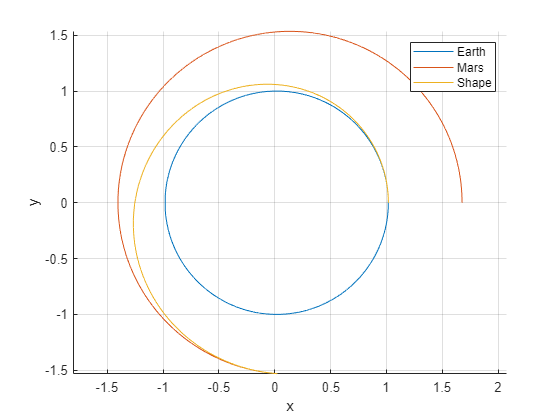

[cr, cq, cz] = ShapeBaseHmT(x0, xf, p.tf);
tr = x0(1) + cr(1) * t + cr(2) * t.^2 / 2 + cr(3) * t.^3 / 3;
tz = x0(3) + cz(1) * t + cz(2) * t.^2 / 2 + cz(3) * t.^3 / 3;
tq = tr;
tq(1) = x0(2);
for i = 2 : length(tq)
    tq(i) = tq(i - 1) + p.tspan * (cq(1) + cq(2) * t(i - 1) + cq(3) * t(i - 1)^2) / tr(i - 1);
end
figure
hold on
plot(x_e(:, 1) .* cos(x_e(:, 2)), x_e(:, 1) .* sin(x_e(:, 2)))
plot(x_m(:, 1) .* cos(x_m(:, 2)), x_m(:, 1) .* sin(x_m(:, 2)))
plot(tr .* cos(tq), tr .* sin(tq))
legend('Earth', 'Mars', 'Shape')
xlabel('x')
ylabel('y')
grid on
axis equal

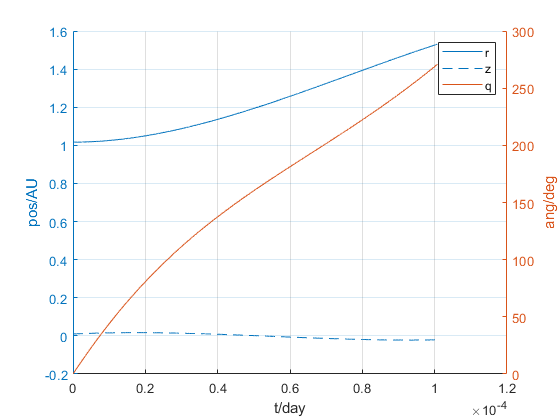

figure
hold on
xlabel('t/day')
yyaxis left
plot(t / 86400, [tr; tz])
ylabel('pos/AU')
yyaxis right
plot(t / 86400, tq * 180 / pi)
ylabel('ang/deg')
legend('r', 'z', 'q')
grid on

#### 验证修正推力

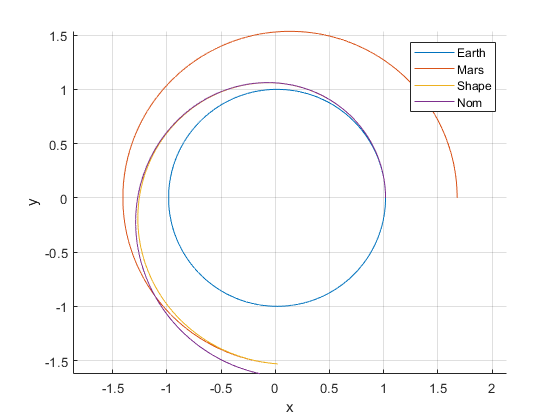

ta = [];
tx = x0;
for i = 2 : length(t)
    [A, B] = HmTSysCtrlMat(t(i), cr, cq, cz, x0, xf, p);
    ta = [ta B(4 : 6)];
    dx = CylinEq(0, tx(:, end), ta(:, end), p);
    tx = [tx tx(:, end) + p.tspan * dx];
end
figure
hold on
plot(x_e(:, 1) .* cos(x_e(:, 2)), x_e(:, 1) .* sin(x_e(:, 2)))
plot(x_m(:, 1) .* cos(x_m(:, 2)), x_m(:, 1) .* sin(x_m(:, 2)))
plot(tr .* cos(tq), tr .* sin(tq))
plot(tx(1, :) .* cos(tx(2, :)), tx(1, :) .* sin(tx(2, :)))
legend('Earth', 'Mars', 'Shape', 'Nom')
xlabel('x')
ylabel('y')
grid on
axis equal

#### 协态变量初值

lambda = ones(6, 1);
lambda = [
-153529331043402
26707451185692.5
-1545055275162.97
-83831500084692.4
-146603791553834
-2590974489152.20
];
for i = 1 : 2
    lambda = ShapeBaseAdjVar(t, cr, cq, cz, x0, xf, p, lambda)
end

### 间接法

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    2.652954e-31    3.953e+00    5.740e-41
    1      14    2.527292e-15    3.953e+00    9.145e+02    2.501e+06
    2      26    2.087038e-15    3.953e+00    1.944e-35    1.601e+06
    3      33    5.180040e-04    3.155e+00    1.637e+13    4.261e+12
    4      40    1.245831e-02    8.712e-01    3.297e+15    3.510e+13
    5      48    1.536123e-02    6.763e-01    3.139e+16    9.072e+13
    6      55    2.976311e-02    2.454e-01    1.281e+16    8.783e+13
    7      62    2.505963e-02    7.521e-03    1.321e+14    2.448e+13
    8      69    2.548917e-02    1.173e-04    2.753e+13    1.955e+12
    9      76    2.549035e-02    1.765e-09    1.215e+11    7.605e+09
   10      89    2.549035e-02    2.318e-09    1.775e-30    3.541e+04

Feasible point with lower objecti

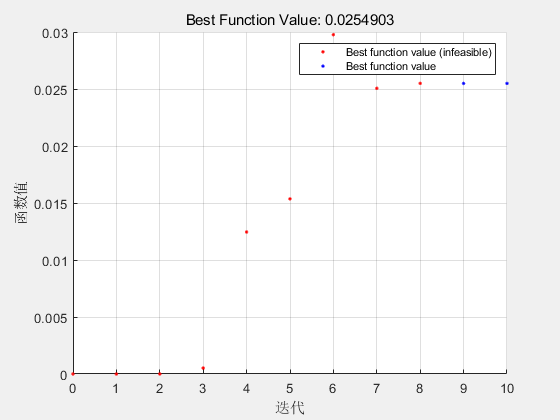


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


lambda = 1.0e+14 *

   -1.5353
    0.2671
   -0.0155
   -0.8383
   -1.4660
   -0.0259


s0 = [x0; lambda; zeros(4, 1)];
if 0
    [~, s] = ode45(@(t, x) CylinEnergyEq(t, x, p), t, s0);
else
    [s, lambda] = IndirOptEnergy(@CylinEnergyEq, x0, xf, p.tf, p);
    s(:, 1) = [];
    lambda
end

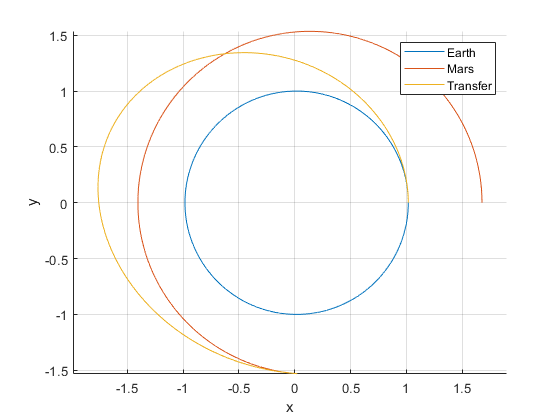

figure
hold on
plot(x_e(:, 1) .* cos(x_e(:, 2)), x_e(:, 1) .* sin(x_e(:, 2)))
plot(x_m(:, 1) .* cos(x_m(:, 2)), x_m(:, 1) .* sin(x_m(:, 2)))
plot(s(:, 1) .* cos(s(:, 2)), s(:, 1) .* sin(s(:, 2)))
legend('Earth', 'Mars', 'Transfer')
xlabel('x')
ylabel('y')
grid on
axis equal

### 形状法(HM, theta)

if false
x0 = x_e(1, :)';
xf = x_m(end, :)';
[cr, ct, cz] = ShapeBaseHm(x0, xf, p.tf);
sspan = 0.01;
s = 0 : sspan : 1;
sq = x0(2) + s * (xf(2) - x0(2));
sr = x0(1) + cr(1) * s + cr(2) * s.^2 / 2 + cr(3) * s.^3 / 3;
st = ct(1) * s + ct(2) * s.^2 / 2 + ct(3) * s.^3 / 3;
sz = x0(3) + cz(1) * s + cz(2) * s.^2 / 2 + cz(3) * s.^3 / 3;
figure
hold on
plot(x_e(:, 1) .* cos(x_e(:, 2)), x_e(:, 1) .* sin(x_e(:, 2)))
plot(x_m(:, 1) .* cos(x_m(:, 2)), x_m(:, 1) .* sin(x_m(:, 2)))
plot(sr .* cos(sq), sr .* sin(sq))
legend('Earth', 'Mars', 'Shape')
xlabel('x')
ylabel('y')
grid on
axis equal
figure
hold on
xlabel('t/day')
yyaxis left
plot(st / 86400, [sr; sz])
ylabel('pos/AU')
yyaxis right
plot(st / 86400, sq * 180 / pi)
ylabel('ang/deg')
legend('r', 'z', 'q')
grid on
end

#### 验证修正推力(有误)

if false
    ta = [];
    tx = x0;
    for i = 1 : length(s)
        [A, B] = HmSysCtrlMat(s(i), cr, ct, cz, x0, xf, p);
        ta = [ta B(4 : 6) / (ct(1) + ct(2) * s(i) + ct(3) * s(i).^2)];
        tdx = CylinEq(0, tx(:, end), ta(:, end), p);
        tx = [tx tx(:, end) + sspan  * tdx * (ct(1) + ct(2) * s(i) + ct(3) * s(i).^2)];
    end
    figure
    hold on
    plot(x_e(:, 1) .* cos(x_e(:, 2)), x_e(:, 1) .* sin(x_e(:, 2)))
    plot(x_m(:, 1) .* cos(x_m(:, 2)), x_m(:, 1) .* sin(x_m(:, 2)))
    plot(sr .* cos(sq), sr .* sin(sq))
    plot(tx(1, :) .* cos(tx(2, :)), tx(1, :) .* sin(tx(2, :)))
    legend('Earth', 'Mars', 'Shape', 'Nom')
    xlabel('x')
    ylabel('y')
    grid on
    axis equal
end